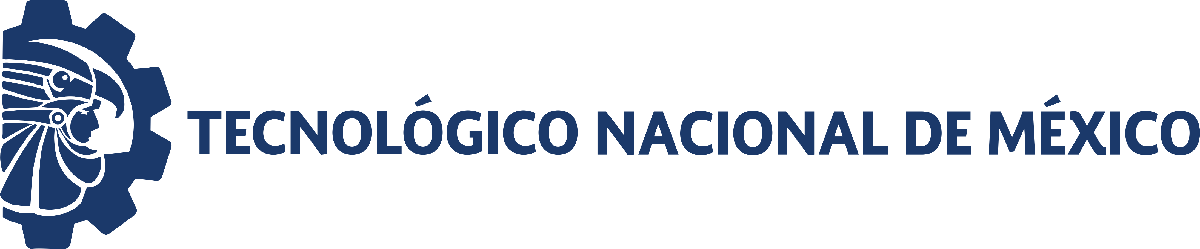                                 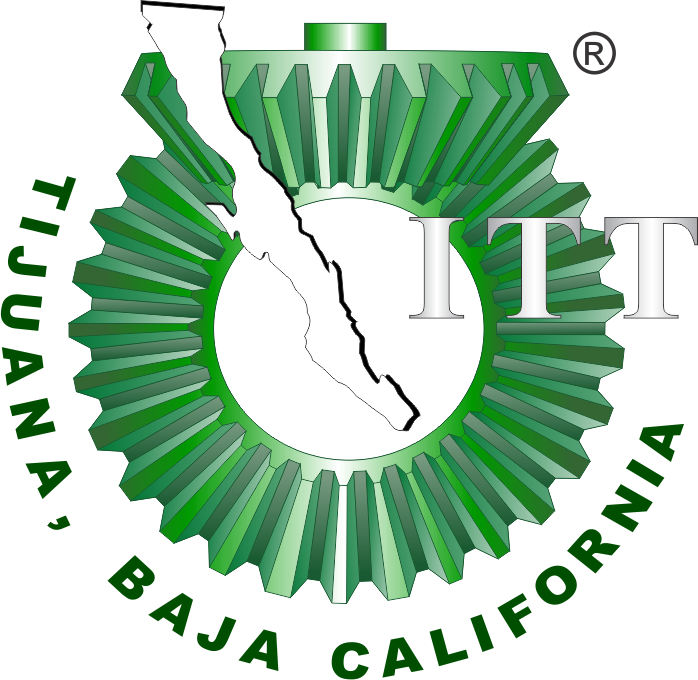

# Parameter estimation on Kluyveromyces marxianus strains through computational modelling and nonlinear regression

**Keywords: **Biomedical Engineering; Control Engineering; Biochemical Engineering; Dynamic Systems.

Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

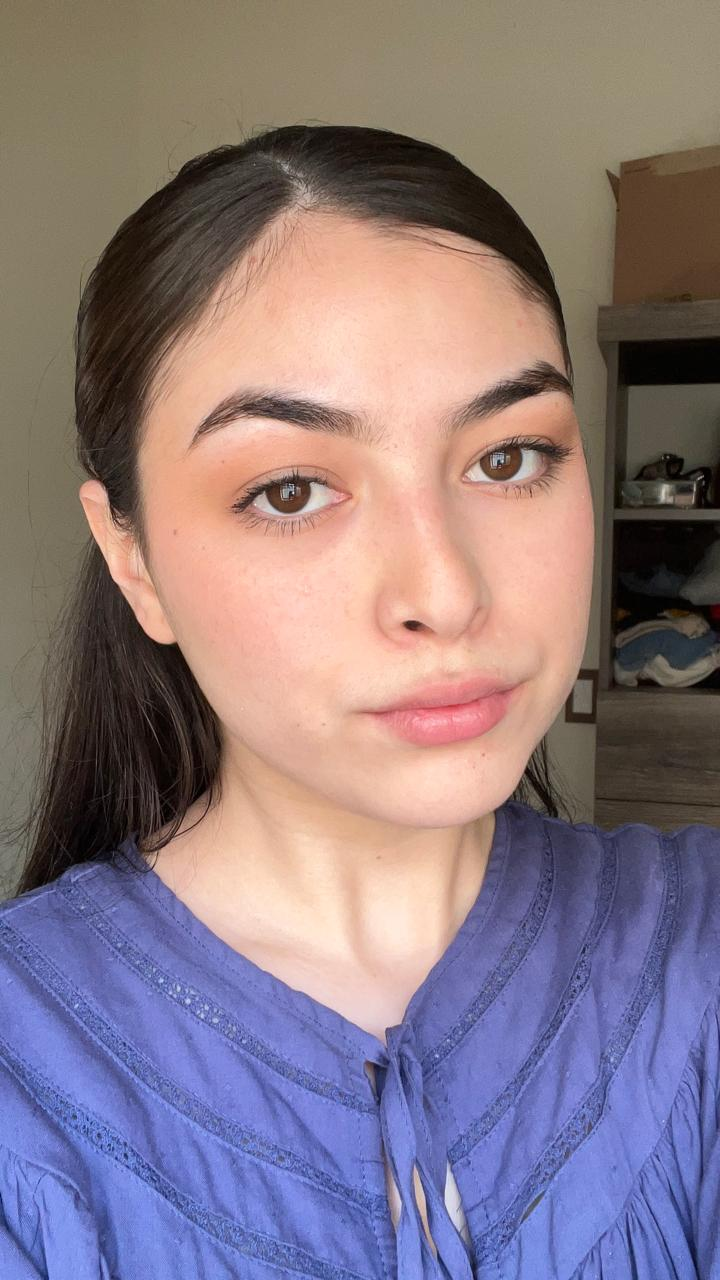

Nombre del alumno: **Mendivil Ramirez Frida Daniela**

Número de control: 20211983

Correo institucional: **L20211983@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Experimental Data **

Biomass experimental data by duplicate in [ g/L ]

clc; clear; close all

sys = readmatrix('data.csv');

Error using readmatrix (line 171)
Unable to find or open 'data.csv'. Check the path and filename or file permissions.

to = round(sys(:,1));
xr = sys(:,2:end); 
strains = ['CBS397  '; 'ITD002  '; 'ITD00157'; 'ITD00268'; 'CBS6556 '];
T = array2table([to, xr], 'VariableNames',{'t [days]', 'CBS397-A', 'CBS397-B', 'ITD002-A', 'ITD002-B', 'ITD00157-A', 'ITD00157-B', 'ITD00268-A', 'ITD00268-B', 'CBS6556-A', 'CBS6556-B'}); 
fprintf('Biomass experimental data by duplicate in [g/L] \n\n'); disp(T)

### Averaging the data

xo = zeros(size(xr,1),size(xr,2)/2);
for i = 1:size(xr,2)/2
    x1 = xr(:,2*i-1);
    x2 = xr(:,2*i);
    xo(:,i) = mean([x1,x2],2);
end
T = array2table([to, xo], 'VariableNames',{'t [days]',...
    'CBS397', 'ITD002', 'ITD00157', 'ITD00268', 'CBS6556'}); 
disp(T) 
plotCepas(to, xo); exportgraphics(gcf,'smoothdata.pdf','ContentType','vector')

### Nonlinear regression: Logistic + Exponential decay

Strains = ['CBS397  '; 'ITD002  '; 'ITD00157'; 'ITD00268'; 'CBS6556 ';...
           'CBS397  '; 'ITD002  '; 'ITD00157'; 'ITD00268'; 'CBS6556 '];
Parameters = ['k '; 'k '; 'k '; 'k '; 'k ';...
              'mu'; 'mu'; 'mu'; 'mu'; 'mu'];
alpha = 0.05;
xmax = zeros(5,1);
phase = zeros(5,1);
Estimate = zeros(length(Parameters),1);
SE = zeros(length(Parameters),1);
Pvalue = zeros(length(Parameters),1);
CI95 = zeros(length(Parameters),2);
dof = zeros(length(Parameters),1);
tval = zeros(length(Parameters),1);
MoE = zeros(length(Parameters),1);

for s = 1:5
    x = xo(:,s);
    xmax(s) = max(x);
    n = find(x == xmax(s));
    tG = to(1:n,1);
    xG = x(1:n,1);
    tD = to(n:end,1) - to(n);
    xD = x(n:end,1);
    phase(s,1) = tG(end); 
    
    [mdlG, mdlD] = fit_ode(tG,xG,tD,xD,xmax(s));
    
    Estimate(s,1) = table2array(mdlG.Coefficients(:,1));
    dof(s,1) = mdlG.DFE;
    tval(s,1) = tinv(1-alpha/2,dof(s,1));
    SE(s,1) = table2array(mdlG.Coefficients(:,2));
    MoE(s,1) = SE(s,1)*tval(s,1);
    CI95(s,:) = coefCI(mdlG,alpha);
    Pvalue(s,1) = table2array(mdlG.Coefficients(:,4));
    
    Estimate(5+s,1) = table2array(mdlD.Coefficients(:,1));
    dof(5+s,1) = mdlD.DFE;
    tval(5+s,1) = tinv(1-alpha/2,dof(5+s,1));
    SE(5+s,1) = table2array(mdlD.Coefficients(:,2));
    MoE(5+s,1) = SE(5+s,1)*tval(5+s,1);
    CI95(5+s,:) = coefCI(mdlD,alpha);
    Pvalue(5+s,1) = table2array(mdlD.Coefficients(:,4));
end

Results = table(Strains,Parameters,dof,tval,Estimate,SE,MoE,CI95,Pvalue);
disp(Results)
for i = 1:5
    [ta,xa(:,i)] = system(Estimate(i),Estimate(i+5),xmax(i),xo(1,i),to(end),phase(i));
end
plotresults(to,xo,ta,xa,phase);...
exportgraphics(gcf,'Results 2EDOS.pdf','ContentType','vector');
 sgtitle('Logistic and exponential decay','Interpreter','latex')

## Nonlinear regression: Cumulative biomass

Strains = ['CBS397  '; 'CBS397  '; 'CBS397  ';...
           'ITD002  '; 'ITD002  '; 'ITD002  ';...
           'ITD00157'; 'ITD00157'; 'ITD00157';...
           'ITD00268'; 'ITD00268'; 'ITD00268';...
           'CBS6556 '; 'CBS6556 '; 'CBS6556 '];
Parameters = ['a'; 'b'; 'm';...
              'a'; 'b'; 'm';...
              'a'; 'b'; 'm';...
              'a'; 'b'; 'm';...
              'a'; 'b'; 'm'];
alpha = 0.05;
estimate = zeros(3,min(size(xo)));
SE = zeros(length(Parameters),1);
Pvalue = zeros(length(Parameters),1);
CI95 = zeros(length(Parameters),2);
AIC = zeros(min(size(xo)),1);
R2 = zeros(min(size(xo)),1);
p0 = [10; 1; 0.001];
integral0 = 0;

for s = 1:5
    xs = xo(:,s);
    mdl = fitting_model(to,xs,integral0,p0);
    estimate(:,s) = table2array(mdl.Coefficients(:,1));
    SE(find(SE == 0):find(SE == 0)+2,1) = table2array(mdl.Coefficients(:,2));
    CI95(find(CI95 == 0):find(CI95 == 0)+2,:) = coefCI(mdl,alpha);
    Pvalue(find(Pvalue == 0):find(Pvalue == 0)+2,1) = table2array(mdl.Coefficients(:,4));
    AIC(s,1) = mdl.ModelCriterion.AICc;
    R2(s,1) = mdl.Rsquared.Adjusted;
end
dof = mdl.DFE;
tval = tinv(1-alpha/2,dof);
MoE = SE.*tval;
fprintf(['\nSample size (n): ', num2str(length(xo(:,1)))]);...
fprintf(['\nParameters to be estimated (pars): ', num2str(numel(p0))]);...
fprintf(['\nDegrees of freedom: ', num2str(dof)]);...
fprintf(['\nSignificance level (alpha): ', num2str(alpha)]);...
fprintf(['\nt-Student value: ', num2str(tval)]);...
fprintf('\nFitting results for each strain');...
Estimate = reshape(estimate,[],1);...
disp(table(Strains,Parameters,Estimate,SE,MoE,CI95,Pvalue));...
fprintf('\nGoodness of fit: Akaike Information Criterion');...
disp(table(strains,AIC));...
fprintf('\nGoodness of fit: R-Squared');...
disp(table(strains,R2));
for i = 1:5
    [ta,xa(:,i)] = systemInt(to,xo(1,i),estimate(:,i),integral0);
end
plotresults(to,xo,ta,xa,phase);...
exportgraphics(gcf,'Results 1EDOS.pdf','ContentType','vector');
sgtitle('Cumulative biomass','Interpreter','latex')

### Function


function plotCepas(t,x)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[2 2 18 24])
      sgtitle('Crecimiento medio de cepas de Kluyveromyces marxianus','Interpreter','latex')

    % Subplot 1 - CBS397
    subplot(5,1,1)
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    plot(t,x(:,1), 'x', 'LineWidth', 1.5, 'Color', [1, 0.41, 0.71])
    xlabel('$t$ [days]', 'Interpreter', 'latex')
    ylabel('$s_1(t)$ [g/L]', 'Interpreter', 'latex')
    legend('$Strain: CBS397$', 'Interpreter','latex','Location','best','Box','off')
    xlim([0 84]); xticks(0:4:84);
    ylim([0 3]); yticks(0:0:3);

    % Subplot 2 - ITD002
    subplot(5,1,2)
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    plot(t, x(:,2), 'x', 'LineWidth', 1.5, 'Color', [0.11, 0.30, 0.42])
    xlabel('$t$ [days]', 'Interpreter', 'latex')
    ylabel('$s_2(t)$ [g/L]', 'Interpreter', 'latex')
    legend('$Strain: ITD002$', 'Interpreter','latex','Location','best','Box','off')
    xlim([0 84]); xticks(0:4:84);
    ylim([0 3]); yticks(0:0:3);

    % Subplot 3 - ITD00157
    subplot(5,1,3)
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    plot(t, x(:,3), 'x', 'LineWidth', 1.5, 'Color', [0.93, 0.69, 0.13])
    xlabel('$t$ [days]', 'Interpreter', 'latex')
    ylabel('$s_3(t)$ [g/L]', 'Interpreter', 'latex')
    legend('$Strain:ITD00157$', 'Interpreter','latex','Location','best','Box','off')
    xlim([0 84]); xticks(0:4:84);
    ylim([0 3]); yticks(0:0:3);

    % Subplot 4 - ITD00268
    subplot(5,1,4)
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    plot(t, x(:,4), 'x', 'LineWidth', 1.5, 'Color', [1, 0.41, 0.71])
    xlabel('$t$ [days]', 'Interpreter', 'latex')
    ylabel('$s_4(t)$ [g/L]', 'Interpreter', 'latex')
    legend('$Strain: ITD00268$', 'Interpreter','latex','Location','best','Box','off')
    xlim([0 84]); xticks(0:4:84);
    ylim([0 3]); yticks(0:0:3);

    % Subplot 5 - CBS6556
    subplot(5,1,5)
    hold on; box on; grid off
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    plot(t, x(:,5), 'x', 'LineWidth', 1.5, 'Color', [0.11, 0.30, 0.42])
    xlabel('$t$ [days]', 'Interpreter', 'latex')
    ylabel('$s_5(t)$ [g/L]', 'Interpreter', 'latex')
    legend('$Strain: CBS6556$', 'Interpreter','latex','Location','best','Box','off')
    xlim([0 84]); xticks(0:4:84);
    ylim([0 3]); yticks(0:0:3);

  
end

### Mathematical model, non-linear regression algorithm and biostatistics

function [mdlG, mdlD] = fit_ode(tG,xG,tD,xD,xmax)
    
    function xa = modelG(k,t)
        dt = 1E-2;
        tend = max(t);
        time = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xG(1);

        for i = 1:n  
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
        end

        function dx = f(x)
            dx = +k*x*(1 - x/xmax);
        end

        xa = zeros(length(t),1);
        for i = 1:length(t)
            j = abs(time-t(i)) < 1E-9;
            xa(i) = x(j); 
        end
    end

    function xa = modelD(mu,t)
        dt = 1E-2;
        tend = max(t);
        time = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xD(1);

        for i=1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
        end

        function dx = f(x)
            dx = -mu*x; 
        end

        xa = zeros(length(t),1);
        for i = 1:length(t)
            j = abs(time-t(i)) < 1E-9;
            xa(i) = x(j); 
        end
    end
    
    k0 = 1; 
    mdlG = fitnlm(tG,xG,@modelG,k0);
    mu0 = 1E-3; 
    mdlD = fitnlm(tD,xD,@modelD,mu0);
end

function [t,x] = system(k,mu,xmax,x0,tend,phase)
    dt = 1E-2;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(n+1,1); x(1) = x0;
    ti = 0;

    for i = 1:n
        ti = ti + dt;
        fx = f(x(i),ti);
        xn = x(i) + fx*dt;
        fxn = f(xn,ti);
        x(i+1) = x(i) + dt*(fx + fxn)/2;
    end

    function dx = f(x,time)
        if time <= phase
            dx = +k*x*(1 - x/xmax);
        elseif time > phase
            dx = - mu*x;
        end
    end
end

function mdl = fitting_model(to,xo,integral0,p0)
    
    function xa = model(p,t)
        a = p(1); b = p(2); m = p(3);
        dt = 1E-2;
        tend = max(t);
        time = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xo(1);
        I = zeros(n+1,1); I(1) = integral0;

        for i = 1:n  
            [fx,fI] = f(x(i),I(i));
            xn = x(i) + fx*dt;
            In = I(i) + fI*dt;
            [fxn,fIn] = f(xn,In);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
            I(i+1) = I(i) + dt*(fI + fIn)/2;
        end

        function [dx,dintegral] = f(x,integral)
            dx = a*x*exp(-b*integral) - m*x;
            dintegral = x;
        end

        xa = zeros(length(t),1);
        for i = 1:length(t)
            j = abs(time-t(i)) < 1E-9;
            xa(i) = x(j); 
        end
    end

    mdl = fitnlm(to,xo,@model,p0);
end

function [t,x] = systemInt(to,xo,p,integral0)
    
        a = p(1); b = p(2); m = p(3);
        dt = 1E-2;
        tend = max(to);
        t = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xo(1);
        I = zeros(n+1,1); I(1) = integral0;

        for i = 1:n  
            [fx,fI] = f(x(i),I(i));
            xn = x(i) + fx*dt;
            In = I(i) + fI*dt;
            [fxn,fIn] = f(xn,In);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
            I(i+1) = I(i) + dt*(fI + fIn)/2;
        end

        function [dx,dintegral] = f(x,integral)
            dx = a*x*exp(-b*integral) - m*x;
            dintegral = x;
        end
end

function mdl = fitting_model2(to,xo,integral0,p0)
    
    function xa = model(p,t)
        a = p(1); b = p(2); c = p(3); m = p(4);
        dt = 1E-2;
        tend = max(t);
        time = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xo(1);
        I = zeros(n+1,1); I(1) = integral0;

        for i = 1:n  
            [fx,fI] = f(x(i),I(i));
            xn = x(i) + fx*dt;
            In = I(i) + fI*dt;
            [fxn,fIn] = f(xn,In);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
            I(i+1) = I(i) + dt*(fI + fIn)/2;
        end

        function [dx,dintegral] = f(x,integral)
            dx = a*x/(1 + c*exp(b*integral)) - m*x;
            dintegral = x;
        end

        xa = zeros(length(t),1);
        for i = 1:length(t)
            j = abs(time-t(i)) < 1E-12;
            xa(i) = x(j); 
        end
    end

    mdl = fitnlm(to,xo,@model,p0);
end

function [t,x] = systemInt2(to,xo,p,integral0)
    
        a = p(1); b = p(2); c = p(3); m = p(4);
        dt = 1E-2;
        tend = max(to);
        t = (0:dt:tend)';
        n = round(tend/dt);
        x = zeros(n+1,1); x(1) = xo(1);
        I = zeros(n+1,1); I(1) = integral0;

        for i = 1:n  
            [fx,fI] = f(x(i),I(i));
            xn = x(i) + fx*dt;
            In = I(i) + fI*dt;
            [fxn,fIn] = f(xn,In);
            x(i+1) = x(i) + dt*(fx + fxn)/2;
            I(i+1) = I(i) + dt*(fI + fIn)/2;
        end

        function [dx,dintegral] = f(x,integral)
            dx = a*x/(1 + c*exp(b*integral)) - m*x;
            dintegral = x;
        end
end

### Results

function plotresults(to,xo,ta,xa,p)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[2 2 18 24])
    bl = [0.11,0.30,0.42];
    grn = [0.25,0.51,0.47];
    rd = [0.65,0.27,0.34];
    orng = [0.85,0.35,0.05];
    prpl = [0.51,0.27,0.56];    
    gry = [0.50,0.50,0.50];

    subplot(5,1,1); grid off; hold on; box on;
    plot(to,xo(:,1),'x','LineWidth',1,'MarkerSize',4,'Color',bl)
    plot(ta,xa(:,1),'-','LineWidth',1,'Color',gry)
    xline(p(1),'--','LineWidth', 0.5);
    annotation('textbox',[0.23 0.84 0.15 0.03], 'String',{'Death phase'},...
    'LineStyle','none', 'FontName','Times New Roman');
    annotation('textbox',[0.17 0.805 0.1 0.03], 'String',{'Growth phase'},...
    'Rotation',60, 'LineStyle','none', 'FontName','Times New Roman', 'FitBoxToText','on');
    xlim([-1,84]); xticks(0:4:84)
    ylim([0,3]); yticks(0:1:3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$s_1(t)$ $[g/L]$','Interpreter','Latex')
    L = legend('$Strain: CBS397$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off')
    set(gca,'Fontname','Times New Roman')

    subplot(5,1,2); grid off; hold on; box on; fontsize(10,'points')
    plot(to,xo(:,2),'x','LineWidth',1,'MarkerSize',4,'Color',grn)
    plot(ta,xa(:,2),'-','LineWidth',1,'Color',gry)
    xline(p(2),'--','LineWidth',1,'Color','k')
    annotation('textbox',[0.23 0.67 0.15 0.03], 'String',{'Death phase'},...
    'LineStyle','none', 'FontName','Times New Roman');
    annotation('textbox',[0.17 0.63 0.1 0.03], 'String',{'Growth phase'},...
    'Rotation',60, 'LineStyle','none', 'FontName','Times New Roman', 'FitBoxToText','on');
    xlim([-1,84]); xticks(0:4:84)
    ylim([0,3]); yticks(0:1:3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$s_2(t)$ $[g/L]$','Interpreter','Latex')
    L = legend('$Strain: ITD002$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off','FontSize',10)
    set(gca,'Fontname','Times New Roman')

    subplot(5,1,3); grid off; hold on; box on; fontsize(10,'points')
    plot(to,xo(:,3),'x','LineWidth',1,'MarkerSize',4,'Color',rd)
    plot(ta,xa(:,3),'-','LineWidth',1,'Color',gry)
    xline(p(3),'--','LineWidth',1,'Color','k')
    annotation('textbox',[0.21 0.50 0.15 0.03], 'String',{'Death phase'},...
    'LineStyle','none', 'FontName','Times New Roman');
     annotation('textbox',[0.17 0.455 0.1 0.03], 'String',{'Growth phase'},...
    'Rotation',70, 'LineStyle','none', 'FontName','Times New Roman', 'FitBoxToText','on');
    xlim([-1,84]); xticks(0:4:84)
    ylim([0,3]); yticks(0:1:3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$s_3(t)$ $[g/L]$','Interpreter','Latex')
    L = legend('$Strain: ITD00157$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off','FontSize',10)
    set(gca,'Fontname','Times New Roman')

    subplot(5,1,4); grid off; hold on; box on; fontsize(10,'points')
    plot(to,xo(:,4),'x','LineWidth',1,'MarkerSize',4,'Color',orng)
    plot(ta,xa(:,4),'-','LineWidth',1,'Color',gry)
    annotation('textbox',[0.23 0.32 0.15 0.03], 'String',{'Death phase'},...
    'LineStyle','none', 'FontName','Times New Roman');
     annotation('textbox',[0.17 0.285 0.1 0.03], 'String',{'Growth phase'},...
    'Rotation',60, 'LineStyle','none', 'FontName','Times New Roman', 'FitBoxToText','on');
    xline(p(4),'--','LineWidth',1,'Color','k')
    xlim([-1,84]); xticks(0:4:84)
    ylim([0,3]); yticks(0:1:3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$s_4(t)$ $[g/L]$','Interpreter','Latex')
    L = legend('$Strain: ITD00268$'); 
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off','FontSize',10)
    set(gca,'Fontname','Times New Roman')

    subplot(5,1,5); grid off; hold on; box on; fontsize(10,'points')
    plot(to,xo(:,5),'x','LineWidth',1,'MarkerSize',4,'Color',prpl)
    plot(ta,xa(:,5),'-','LineWidth',1,'Color',gry)
    xline(p(5),'--','LineWidth',1,'Color','k')
    annotation('textbox',[0.27 0.15 0.15 0.03], 'String',{'Death phase'},...
    'LineStyle','none', 'FontName','Times New Roman');
     annotation('textbox',[0.17 0.115 0.1 0.03], 'String',{'Growth phase'},...
    'Rotation',60, 'LineStyle','none', 'FontName','Times New Roman', 'FitBoxToText','on');
    xlim([-1,84]); xticks(0:4:84)
    ylim([0,3]); yticks(0:1:3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$s_5(t)$ $[g/L]$','Interpreter','Latex')
    L = legend('$Strain: CBS6556$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off','FontSize',10)
    set(gca,'Fontname','Times New Roman')
end